# Cart-Pendulum Problem

The equations of motion for the cart and the pendulum are as follows, where:

g = gravity = 9.8 m/s^2

I = inertial constant of the pendulum

b = damping coefficient of friction of the cart

x = cart position

th = theta = pendulum angle w.r.t. vertical down

syms M m x_ddot x_dot x theta_ddot theta_dot theta l b I g F
eqn_cart = M*x_ddot == F - m*x_ddot - m*l*theta_ddot*cos(theta) + m*l*theta_dot^2 - b*x_dot

$$eqn\_cart = M\,\ddot{x}=l\,m\,{\dot{\theta }}^{2}+F-b\,\dot{x}-m\,\ddot{x}-l\,m\,\ddot{\theta }\,\cos\left(\theta \right)$$

eqn_pend = theta_ddot*(m*l^2 + I) == -m*g*l*sin(theta) - m*l*cos(theta)*x_ddot

$$eqn\_pend = \ddot{\theta }\,\left(m\,l^{2}+\text{I}\right)=-g\,l\,m\,\sin\left(\theta \right)-l\,m\,\ddot{x}\,\cos\left(\theta \right)$$


% Deriving the solutions for ONLY x_ddot and theta_ddot
[x_sol, theta_sol] = solve([eqn_pend,eqn_cart],[x_ddot,theta_ddot])

$$x\_sol = \frac{F\,\text{I}-\text{I}\,b\,\dot{x}+l^{3}\,m^{2}\,{\dot{\theta }}^{2}+F\,l^{2}\,m+\text{I}\,l\,m\,{\dot{\theta }}^{2}-b\,l^{2}\,m\,\dot{x}+g\,l^{2}\,m^{2}\,\cos\left(\theta \right)\,\sin\left(\theta \right)}{-l^{2}\,m^{2}\,{\cos\left(\theta \right)}^{2}+l^{2}\,m^{2}+M\,l^{2}\,m+\text{I}\,m+\text{I}\,M}$$

$$theta\_sol = -\frac{l\,m\,\left(l\,m\,\cos\left(\theta \right)\,{\dot{\theta }}^{2}+F\,\cos\left(\theta \right)-b\,\dot{x}\,\cos\left(\theta \right)+g\,m\,\sin\left(\theta \right)+M\,g\,\sin\left(\theta \right)\right)}{-l^{2}\,m^{2}\,{\cos\left(\theta \right)}^{2}+l^{2}\,m^{2}+M\,l^{2}\,m+\text{I}\,m+\text{I}\,M}$$

## Setting up the State-space equations

syms beta_1 beta_2 beta_3 beta_4 u t
% f = [beta_1_dot; beta_2_dot; beta_3_dot; beta_4_dot] 
%   = [x_dot; x_ddot; theta_dot; theta_ddot]
f = [x_dot;
    x_sol;
    theta_dot;
    theta_sol]

$$f = \begin{array}{l} \left(\begin{array}{c} \dot{x}\\ \frac{F\,\text{I}-\text{I}\,b\,\dot{x}+l^{3}\,m^{2}\,{\dot{\theta }}^{2}+F\,l^{2}\,m+\text{I}\,l\,m\,{\dot{\theta }}^{2}-b\,l^{2}\,m\,\dot{x}+g\,l^{2}\,m^{2}\,\cos\left(\theta \right)\,\sin\left(\theta \right)}{\sigma_{1}}\\ \dot{\theta }\\ -\frac{l\,m\,\left(l\,m\,\cos\left(\theta \right)\,{\dot{\theta }}^{2}+F\,\cos\left(\theta \right)-b\,\dot{x}\,\cos\left(\theta \right)+g\,m\,\sin\left(\theta \right)+M\,g\,\sin\left(\theta \right)\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-l^{2}\,m^{2}\,{\cos\left(\theta \right)}^{2}+l^{2}\,m^{2}+M\,l^{2}\,m+\text{I}\,m+\text{I}\,M \end{array}$$

f = subs(f,[x, x_dot, theta, theta_dot, F],[beta_1, beta_2, beta_3, beta_4, u])

$$f = \begin{array}{l} \left(\begin{array}{c} \beta_{2}\\ \frac{\text{I}\,u+l^{2}\,m\,u-\text{I}\,b\,\beta_{2}+{\beta_{4}}^{2}\,l^{3}\,m^{2}+\text{I}\,{\beta_{4}}^{2}\,l\,m-b\,\beta_{2}\,l^{2}\,m+g\,l^{2}\,m^{2}\,\cos\left(\beta_{3}\right)\,\sin\left(\beta_{3}\right)}{\sigma_{1}}\\ \beta_{4}\\ -\frac{l\,m\,\left(l\,m\,\cos\left(\beta_{3}\right)\,{\beta_{4}}^{2}+u\,\cos\left(\beta_{3}\right)+g\,m\,\sin\left(\beta_{3}\right)+M\,g\,\sin\left(\beta_{3}\right)-b\,\beta_{2}\,\cos\left(\beta_{3}\right)\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-l^{2}\,m^{2}\,{\cos\left(\beta_{3}\right)}^{2}+l^{2}\,m^{2}+M\,l^{2}\,m+\text{I}\,m+\text{I}\,M \end{array}$$

beta = [beta_1; beta_2; beta_3; beta_4]

$$beta = \left(\begin{array}{c} \beta_{1}\\ \beta_{2}\\ \beta_{3}\\ \beta_{4} \end{array}\right)$$

Asym = jacobian(f,beta)

$$Asym = \begin{array}{l} \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & -\frac{b\,m\,l^{2}+\text{I}\,b}{\sigma_{1}} & \frac{g\,l^{2}\,m^{2}\,{\cos\left(\beta_{3}\right)}^{2}-g\,l^{2}\,m^{2}\,{\sin\left(\beta_{3}\right)}^{2}}{\sigma_{1}}-\frac{2\,l^{2}\,m^{2}\,\cos\left(\beta_{3}\right)\,\sin\left(\beta_{3}\right)\,\left(\text{I}\,u+l^{2}\,m\,u-\text{I}\,b\,\beta_{2}+{\beta_{4}}^{2}\,l^{3}\,m^{2}+\text{I}\,{\beta_{4}}^{2}\,l\,m-b\,\beta_{2}\,l^{2}\,m+g\,l^{2}\,m^{2}\,\cos\left(\beta_{3}\right)\,\sin\left(\beta_{3}\right)\right)}{{\sigma_{1}}^{2}} & \frac{2\,\beta_{4}\,l^{3}\,m^{2}+2\,\text{I}\,\beta_{4}\,l\,m}{\sigma_{1}}\\ 0 & 0 & 0 & 1\\ 0 & \frac{b\,l\,m\,\cos\left(\beta_{3}\right)}{\sigma_{1}} & \frac{2\,l^{3}\,m^{3}\,\cos\left(\beta_{3}\right)\,\sin\left(\beta_{3}\right)\,\left(l\,m\,\cos\left(\beta_{3}\right)\,{\beta_{4}}^{2}+u\,\cos\left(\beta_{3}\right)+g\,m\,\sin\left(\beta_{3}\right)+M\,g\,\sin\left(\beta_{3}\right)-b\,\beta_{2}\,\cos\left(\beta_{3}\right)\right)}{{\sigma_{1}}^{2}}-\frac{l\,m\,\left(-l\,m\,\sin\left(\beta_{3}\right)\,{\beta_{4}}^{2}-u\,\sin\left(\beta_{3}\right)+M\,g\,\cos\left(\beta_{3}\right)+g\,m\,\cos\left(\beta_{3}\right)+b\,\beta_{2}\,\sin\left(\beta_{3}\right)\right)}{\sigma_{1}} & -\frac{2\,\beta_{4}\,l^{2}\,m^{2}\,\cos\left(\beta_{3}\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-l^{2}\,m^{2}\,{\cos\left(\beta_{3}\right)}^{2}+l^{2}\,m^{2}+M\,l^{2}\,m+\text{I}\,m+\text{I}\,M \end{array}$$

Bsym = jacobian(f,u)

$$Bsym = \begin{array}{l} \left(\begin{array}{c} 0\\ \frac{m\,l^{2}+\text{I}}{\sigma_{1}}\\ 0\\ -\frac{l\,m\,\cos\left(\beta_{3}\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-l^{2}\,m^{2}\,{\cos\left(\beta_{3}\right)}^{2}+l^{2}\,m^{2}+M\,l^{2}\,m+\text{I}\,m+\text{I}\,M \end{array}$$

% system was linearized at equil. points (no movement), where theta = 0,pi
% and x is not constrained. Thus, substituting in the equil point where
% theta = pi ;
Api = subs(Asym,[beta_1, beta_2, beta_3, beta_4], [0, 0, pi, 0])

$$Api = \begin{array}{l} \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & -\frac{b\,m\,l^{2}+\text{I}\,b}{\sigma_{1}} & \frac{g\,l^{2}\,m^{2}}{\sigma_{1}} & 0\\ 0 & 0 & 0 & 1\\ 0 & -\frac{b\,l\,m}{\sigma_{1}} & \frac{l\,m\,\left(M\,g+g\,m\right)}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=M\,m\,l^{2}+\text{I}\,m+\text{I}\,M \end{array}$$

Bpi = subs(Bsym,[beta_1, beta_2, beta_3, beta_4], [0, 0, pi, 0])

$$Bpi = \left(\begin{array}{c} 0\\ \frac{m\,l^{2}+\text{I}}{M\,m\,l^{2}+\text{I}\,m+\text{I}\,M}\\ 0\\ \frac{l\,m}{M\,m\,l^{2}+\text{I}\,m+\text{I}\,M} \end{array}\right)$$


% Thus, our linearized state-space representation of the system can be
% represented as: diff(beta,t) = Api*beta + Bpi*u

% where beta_3 is the deviation from the equil point, phi


## Inserting real values and creating State Space object

g_real = 9.8; % m/sec^2
M_real = 0.5; % kg - mass of cart
m_real = 0.2; % kg - mass of pendulum
b_real = 0.1; % N/m/sec
l_real = 0.3; % m - length to pendulum CoM
I_real = 0.006; % kg*m^2 - mass moment of inertia of the pendulum (1/12*m*(length)^2)
% for inertial calculation, assume uniform rod of negligible thickness,
% with inertia calculated about it's center. 
% reference: http://hyperphysics.phy-astr.gsu.edu/hbase/hframe.html
A = double(subs(Api,[g,M,m,b,l,I],[g_real,M_real,m_real,b_real,l_real,I_real]));
B = double(subs(Bpi,[g,M,m,b,l,I],[g_real,M_real,m_real,b_real,l_real,I_real]));
% outputting both the x-position and theta-angle
C = [1 0 0 0; 0 0 1 0];
D = [0;0];
states = {'x' 'x_dot' 'phi' 'phi_dot'};
inputs = {'u'};
outputs = {'x'; 'theta'};
olsys = ss(A,B,C,D,'statename',states,'inputname',inputs,'outputname',outputs)

olsys =
 
  A = 
                  x    x_dot      phi  phi_dot
   x              0        1        0        0
   x_dot          0  -0.1818    2.673        0
   phi            0        0        0        1
   phi_dot        0  -0.4545    31.18        0
 
  B = 
                u
   x            0
   x_dot    1.818
   phi          0
   phi_dot  4.545
 
  C = 
                x    x_dot      phi  phi_dot
   x            1        0        0        0
   theta        0        0        1        0
 
  D = 
          u
   x      0
   theta  0
 
Continuous-time state-space model.



% initial(olsys,[0;0;7*pi/8;0],10) % this system blows up because we
% LINEARIZED around pi (vertical up), not 0 (vertical down)
olsys_tf = tf(olsys)

olsys_tf =
 
  From input "u" to output...
          1.818 s^2 + 1.615e-15 s - 44.55
   x:  --------------------------------------
       s^4 + 0.1818 s^3 - 31.18 s^2 - 4.455 s
 
                  4.545 s + 2.718e-16
   theta:  ----------------------------------
           s^3 + 0.1818 s^2 - 31.18 s - 4.455
 
Continuous-time transfer function.



## Stabilizing the System with SS Feedback gain

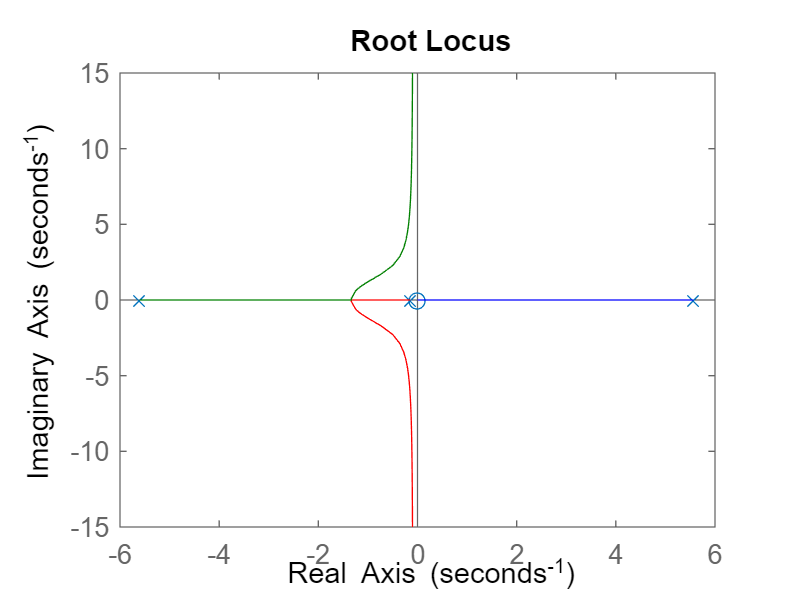

figure;
rlocus(olsys_tf(2))

% from the root locus plot theta/u, we see that there will always be a pole
% in the RHP, so we have to do a state-space feedback to stabilize the system

% seeing if the system is controllable and observable (full rank = yes)
rank(ctrb(A,B))

ans = 4

rank(obsv(A,C))

ans = 4


p = [-3, -4, -5, -6];
K = acker(A,B,p)

K =    -8.0816   -7.7776   36.2727    7.0310


Abar = A-B*K;
clsys = ss(Abar,B,C,D,'statename',states,'inputname',inputs,'outputname',outputs)

clsys =
 
  A = 
                  x    x_dot      phi  phi_dot
   x              0        1        0        0
   x_dot      14.69    13.96   -63.28   -12.78
   phi            0        0        0        1
   phi_dot    36.73     34.9   -133.7   -31.96
 
  B = 
                u
   x            0
   x_dot    1.818
   phi          0
   phi_dot  4.545
 
  C = 
                x    x_dot      phi  phi_dot
   x            1        0        0        0
   theta        0        0        1        0
 
  D = 
          u
   x      0
   theta  0
 
Continuous-time state-space model.



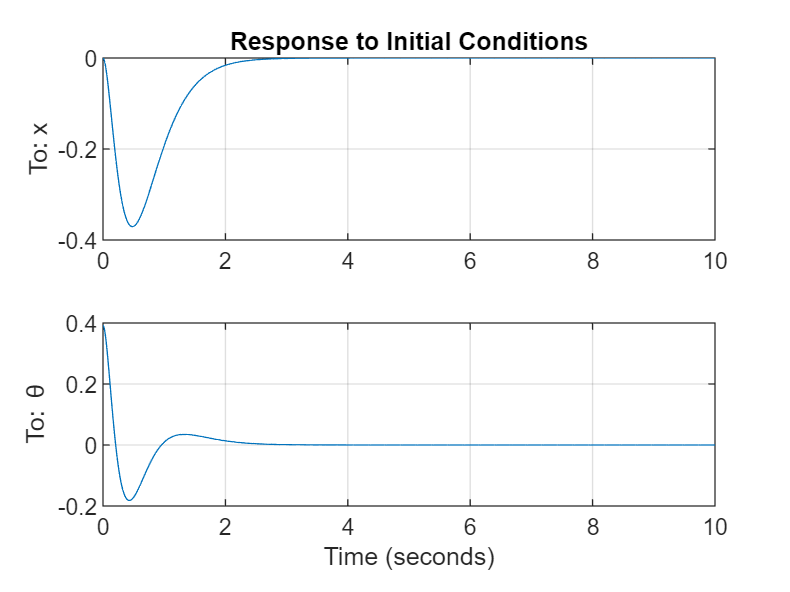

[y_init,t_init,beta_state_init] = initial(clsys,[0;0;pi/8;0],10);
figure;
tiledlayout(2,1);
nexttile;
plot(t_init, y_init(:,1)); title('Response to Initial Conditions'); ylabel('To: x');
grid on
nexttile;
plot(t_init,y_init(:,2)); ylabel('To: \theta'); xlabel('Time (seconds)')
grid on

## Desired output tracking

yd = [1; 0]; % x position: 1m, phi: 0rad deviation
clsys_gain = -C/Abar*B % this is the gain of the system with a step input

clsys_gain =    -0.1237
         0


% from clsys_gain, we can see that phi will always return to 0, so we can
% only control the output x:
r1 = yd(1)/clsys_gain(1); % reference input

figure;
% step response with defined input so that output is at desired location
[y,t,beta_state] = step(clsys*r1);

### Animating the desired output tracking - NEXT STEP

x = beta_state_init(:,1);
theta = beta_state_init(:,3);
slen = 0.2;
sq = [  -slen  slen   slen   -slen  -slen;
        0   0   slen   slen   0]; % the vertex locations of the cart
figure;
cart = plot(sq(1,:),sq(2,:),'r');
hold on

th = linspace(0,2*pi) ; % the points for generating the plot of a circle
r1 = 0.01; % radius of circle 1 (CoM)..?

cB = [0; l_real]; % initial x-axis location of the pendulum CoM, B-frame
eB = 2*cB; % initial x-axis location of the END of the pendulum 
R_AB = [cos(theta(1)) sin(theta(1)); -sin(theta(1)) cos(theta(1))]; % rotational matrix
d_AB = [0; slen]; % location of center of B-frame w.r.t. A-frame
g_AB = [R_AB d_AB; 0 0 1]; % transformation matrix
cA = g_AB*[cB; 1]; cA = cA(1:2);

eA = g_AB*[eB; 1]; eA = eA(1:2);

CoMx = cA(1) + r1*cos(th) ; 
CoMy = cA(2) + r1*sin(th) ;

CoM = plot(CoMx,CoMy,'bl') ;
bar = plot([d_AB(1) eA(1)], [d_AB(2) eA(2)],'b')

bar =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0.2296]
              YData: [0.2000 0.7543]
              ZData: [1×0 double]

  Show all properties


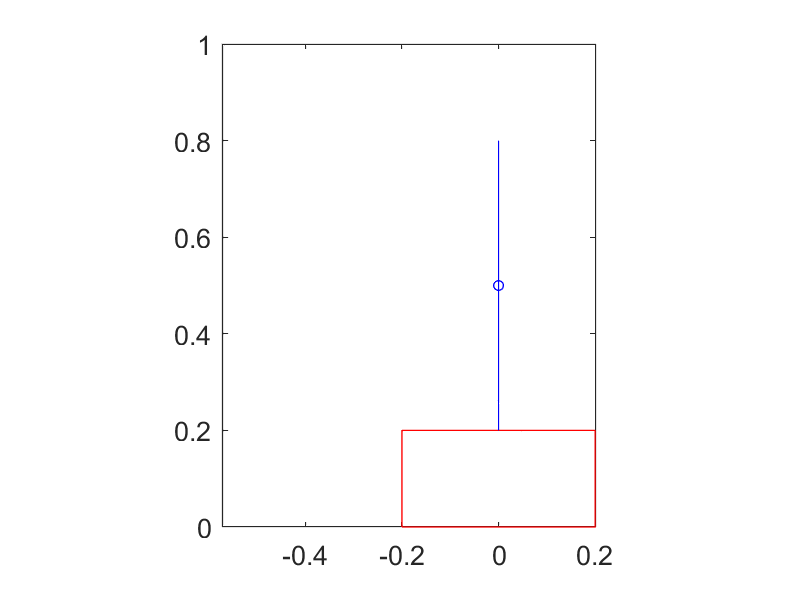

axis equal
minx = min(x)-slen;
maxx = max(x)+slen;
axis([minx maxx 0 1]) 

%% animation
for i = 2:length(x)
    sq_draw = sq + [repmat(x(i),[1,size(sq,2)]); zeros(1,size(sq,2))];
    
    R_AB = [cos(theta(i)) -sin(theta(i)); sin(theta(i)) cos(theta(i))]; % rotational matrix
    d_AB = [x(i); slen]; % location of center of B-frame w.r.t. A-frame
    g_AB = [R_AB d_AB; 0 0 1]; % transformation matrix
    cA = g_AB*[cB; 1]; cA = cA(1:2);
    eA = g_AB*[eB; 1]; eA = eA(1:2);
    
    CoMx = cA(1) + r1*cos(th) ; 
    CoMy = cA(2) + r1*sin(th) ;
    bar_x = [d_AB(1) eA(1)];
    bar_y = [d_AB(2) eA(2)];

    set(cart,'XData',sq_draw(1,:),'YData',sq_draw(2,:)) ;
    set(CoM,'XData',CoMx,'YData',CoMy) ;
    set(bar,'XData',bar_x,'YData',bar_y) ;
    axis([minx maxx 0 1])     
    drawnow
    pause(0.05)
end

**Done: Figure out why the angle is negative from the simulation... (it was my definition of the rotation matrix)**

NEXT STEPS:

- add in diagrams at the beginning to illustrate the angles and what the different variables mean so when I show this to someone else it's very clear (like I've written a paper or something on it)

- get the integral control working, 

- discretize the control solutions (state space, integral, optimal)

- then do an optimal control solution